%%Problem1: LeadCompensator for Speed Improvement


TASK-A

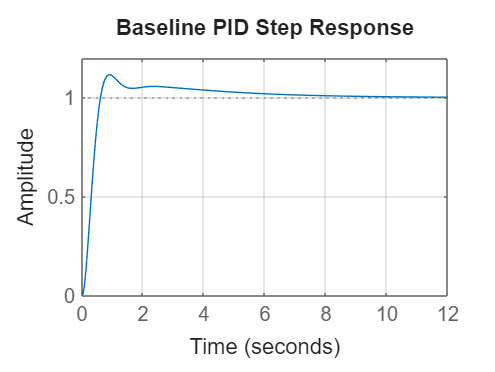

%% Plant
s = tf('s');
G = 20/(s*(s+2)*(s+5));
C_pid = pidtune(G,'PID');
T_pid = feedback(C_pid*G,1);

%% Step Response
figure;
step(T_pid);
grid on;
title('Baseline PID Step Response');


info_pid = stepinfo(T_pid)

info_pid = struct with fields:
         RiseTime: 0.4083
    TransientTime: 5.9509
     SettlingTime: 5.9509
      SettlingMin: 0.9285
      SettlingMax: 1.1154
        Overshoot: 11.5379
       Undershoot: 0
             Peak: 1.1154
         PeakTime: 0.9107


TASK-B

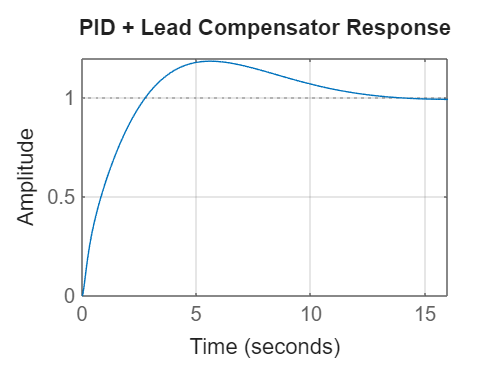

z = 3;
p = 15;
Kc = 1;   

C_lead = Kc * (s+z)/(s+p);

%% Combined controller
C_total = C_pid * C_lead;
T_lead = feedback(C_total*G,1);

figure;
step(T_lead);
grid on;
title('PID + Lead Compensator Response');


info_lead = stepinfo(T_lead)

info_lead = struct with fields:
         RiseTime: 2.0745
    TransientTime: 12.1338
     SettlingTime: 12.1338
      SettlingMin: 0.9002
      SettlingMax: 1.1838
        Overshoot: 18.3815
       Undershoot: 0
             Peak: 1.1838
         PeakTime: 5.6150


TASK-C

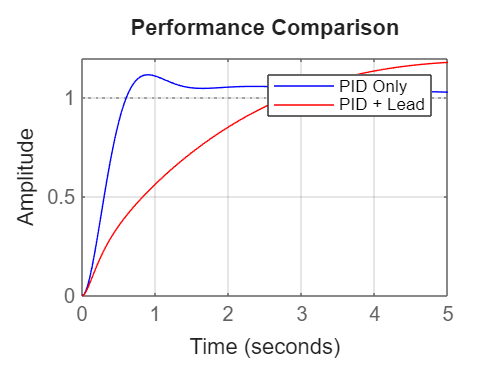

figure;
step(T_pid,'b',T_lead,'r',5);
grid on;
legend('PID Only','PID + Lead');
title('Performance Comparison');


MP_pid = info_pid.Overshoot;
Ts_pid = info_pid.SettlingTime;
Tr_pid = info_pid.RiseTime;

MP_lead = info_lead.Overshoot;
Ts_lead = info_lead.SettlingTime;
Tr_lead = info_lead.RiseTime;

T = table( ...
    [Tr_pid; Tr_lead], ...
    [Ts_pid; Ts_lead], ...
    [MP_pid; MP_lead], ...
    'VariableNames',{'RiseTime','SettlingTime','Overshoot'}, ...
    'RowNames',{'PID','PID+Lead'})

T = 2×3 table
                RiseTime    SettlingTime    Overshoot
                ________    ____________    _________

    PID         0.40833        5.9509        11.538  
    PID+Lead     2.0745        12.134        18.382  


Lead compensator primarily improves:

-response speed

-damping ratio

-stability margin

TASK-D

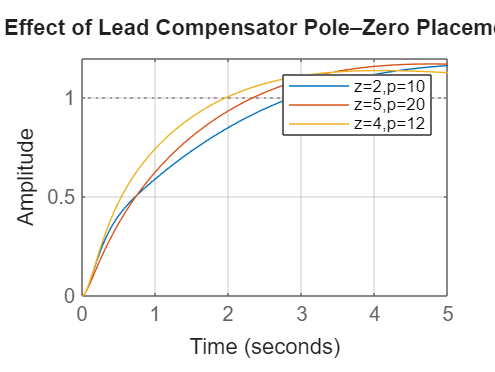

configs = [2 10; 5 20; 4 12];

figure; hold on;

for k = 1:size(configs,1)

    z = configs(k,1);
    p = configs(k,2);

    C_lead = Kc * (s+z)/(s+p);
    T_test = feedback(C_pid*C_lead*G,1);

    step(T_test,5);
end

legend('z=2,p=10','z=5,p=20','z=4,p=12');
grid on;
title('Effect of Lead Compensator Pole–Zero Placement');

PROBLEM-2

TASK-A

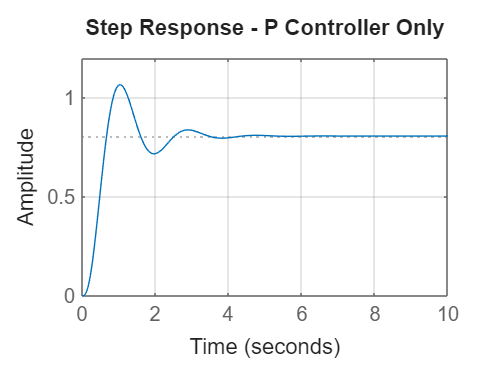

%% Problem 2 
s = tf('s');
G = 50/((s+1)*(s+3)*(s+8));

Kp = 2;
C_p = Kp;

T_p = feedback(C_p*G,1);

figure;
step(T_p,10);
grid on;
title('Step Response - P Controller Only');


info_p = stepinfo(T_p)

info_p = struct with fields:
         RiseTime: 0.4121
    TransientTime: 3.2198
     SettlingTime: 3.2198
      SettlingMin: 0.7170
      SettlingMax: 1.0652
        Overshoot: 32.0842
       Undershoot: 0
             Peak: 1.0652
         PeakTime: 1.0433



[y_p,t] = step(T_p);
yss_p = y_p(end);     
ess_p = 1 - yss_p      

ess_p = 0.1920

TASK-B

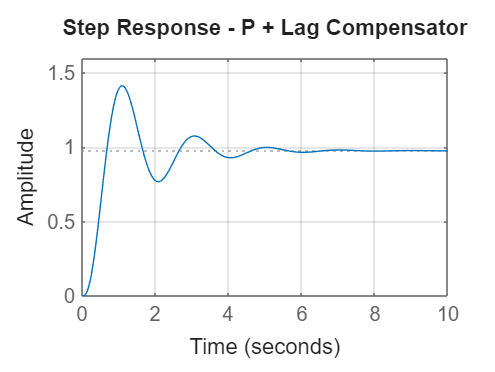

z = 1;
p = 0.1;
Kc = 1;

C_lag = Kc*(s+z)/(s+p);

%% Combined Controller
C_total = C_p * C_lag;

T_lag = feedback(C_total*G,1);

figure;
step(T_lag,10);
grid on;
title('Step Response - P + Lag Compensator');


info_lag = stepinfo(T_lag)

info_lag = struct with fields:
         RiseTime: 0.4101
    TransientTime: 5.2126
     SettlingTime: 5.2126
      SettlingMin: 0.7686
      SettlingMax: 1.4137
        Overshoot: 44.7626
       Undershoot: 0
             Peak: 1.4137
         PeakTime: 1.0941



[y_lag,t] = step(T_lag);
yss_lag = y_lag(end);
ess_lag = 1 - yss_lag

ess_lag = 0.0254

TASK-C

ErrorReduction = (ess_p - ess_lag)/ess_p * 100;

T = table( ...
    ess_p, ...
    ess_lag, ...
    ErrorReduction, ...
    info_p.SettlingTime, ...
    info_lag.SettlingTime, ...
    'VariableNames', {'e_ss_P','e_ss_Lag','Error_Reduction','Ts_P','Ts_Lag'} ...
)

T = 1×5 table
    e_ss_P     e_ss_Lag    Error_Reduction     Ts_P     Ts_Lag
    _______    ________    _______________    ______    ______

    0.19202    0.025389        86.778         3.2198    5.2126


A lag compensator reduces steady-state error because it increases the low-frequency (DC) gain of the closed-loop system.

Since steady-state error is inversely related to DC gain, boosting the gain at low frequencies improves step tracking accuracy.

However, the additional pole introduced by the lag compensator slows the transient response, increasing settling time. Thus, lag compensation trades transient speed for improved steady-state accuracy.

TASK-D

%%Task-D

Lag compensators intentionally introduce a **slow pole** near origin.

That pole:

- pulls dominant poles toward imaginary axis

- increases time constant

- slows transient response

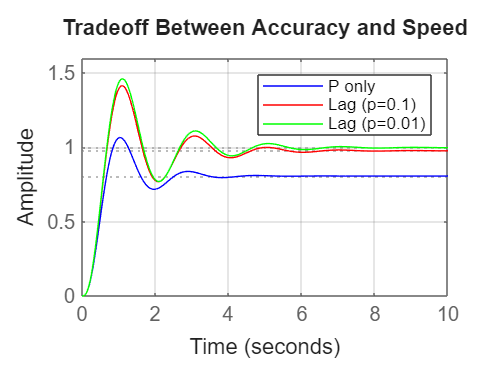

p = 0.01;
C_lag_strong = Kc*(s+z)/(s+p);

T_lag2 = feedback(C_p*C_lag_strong*G,1);

figure;
step(T_p,'b',T_lag,'r',T_lag2,'g',10);
legend('P only','Lag (p=0.1)','Lag (p=0.01)');
grid on;
title('Tradeoff Between Accuracy and Speed');

- Lag compensator improves steady-state performance

- but degrades transient performance.

PROBLEM-3

%%Problem 3: Feedforward + Feedback Control

s = tf('s');
G = 1/(s+0.5);
Kp = 2;
Ki = 1;
Cfb = Kp + Ki/s;
T_fb = feedback(Cfb*G,1);
t = 0:0.01:25;
r = ones(size(t));     
d = 0.3 * (t >= 5);

[y_fb,~,x_fb] = lsim(T_fb,r,t);


y_fb = y_fb - d;

e_fb = r - y_fb;

TASK-B

%% Feedforward gain
Kff = 0.5;

y_ff = zeros(size(t));
e_int = 0;

dt = t(2)-t(1);

for i = 2:length(t)

    % disturbance (known)
    d = 0;
    if t(i) >= 5
        d = 0.3;
    end

    % feedback controller
    e = r(i) - y_ff(i-1);
    u_fb = Kp*e + Ki*e_int;

    % integrate error
    e_int = e_int + e*dt;

    % feedforward compensation
    u_ff = Kff * d;

    % total control
    u_total = u_fb + u_ff;

    % plant update (discrete approx)
    y_ff(i) = y_ff(i-1) + dt*(-0.5*y_ff(i-1) + u_total) - d;
end

e_ff = r - y_ff;

TASK-C

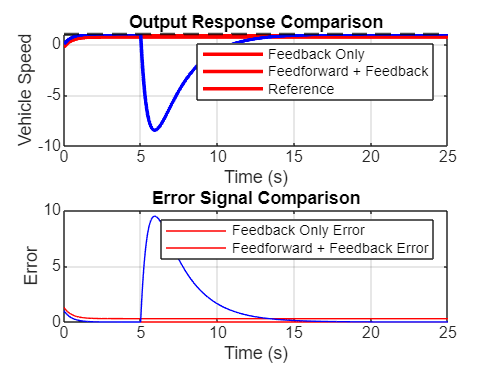


figure;
subplot(2,1,1);
plot(t,y_fb,'r','LineWidth',1.8); hold on;
plot(t,y_ff,'b','LineWidth',1.8);
yline(1,'--k','LineWidth',1.2);
grid on;
legend('Feedback Only','Feedforward + Feedback','Reference');
title('Output Response Comparison');
xlabel('Time (s)');
ylabel('Vehicle Speed');

subplot(2,1,2);
plot(t,e_fb,'r'); hold on;
plot(t,e_ff,'b');
grid on;
legend('Feedback Only Error','Feedforward + Feedback Error');
title('Error Signal Comparison');
xlabel('Time (s)');
ylabel('Error');

- Feedback reacts **after** disturbance

- Feedforward cancels **before error develops**

TASK-D

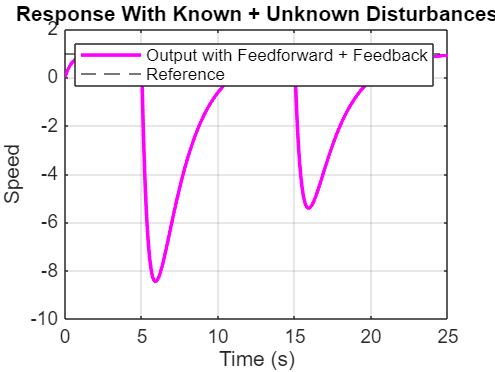


d_known = (t >= 5) * 0.3;
d_unpred = (t >= 15) * 0.2;

d_total = d_known + d_unpred;

y_mix = zeros(size(t));
e_int = 0;

for i = 2:length(t)

    % feedback controller
    e = r(i) - y_mix(i-1);
    u_fb = Kp*e + Ki*e_int;
    e_int = e_int + e*dt;

    % feedforward ONLY compensates known disturbance
    if t(i) >= 5
        u_ff = Kff * 0.3;
    else
        u_ff = 0;
    end

    u_total = u_fb + u_ff;

    % plant with BOTH disturbances
    y_mix(i) = y_mix(i-1) + dt*(-0.5*y_mix(i-1) + u_total) ...
               - d_total(i);
end

e_mix = r - y_mix;

figure;
plot(t,y_mix,'m','LineWidth',1.8); hold on;
yline(1,'--k');
grid on;
title('Response With Known + Unknown Disturbances');
legend('Output with Feedforward + Feedback','Reference');
xlabel('Time (s)');
ylabel('Speed');

Feedforward compensation provides fast disturbance rejection when disturbances are measurable or predictable, while feedback control ensures robustness against unknown or unmodeled disturbances.

%%Problem 4: Simple MIMO System Control


TASK-A

s = tf('s');

G11 = 2/(s+1);
G12 = 0.5/(s+2);
G21 = 1/(s+1.5);
G22 = 3/(s+1);

G = [G11 G12;
     G21 G22];   % 2x2 MIMO system

Case-1

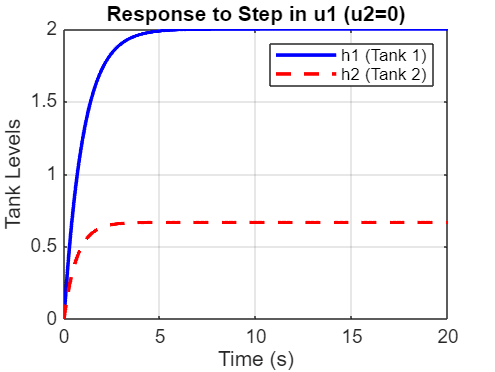


t = 0:0.01:20;
u1 = ones(size(t));   % step to u1
u2 = zeros(size(t));  % no input to u2
u = [u1; u2]';

[y1,~] = lsim(G,u,t);

figure;
plot(t,y1(:,1),'b','LineWidth',1.8); hold on;
plot(t,y1(:,2),'r--','LineWidth',1.8);
grid on;
legend('h1 (Tank 1)','h2 (Tank 2)');
title('Response to Step in u1 (u2=0)');
xlabel('Time (s)');
ylabel('Tank Levels');

Case-2

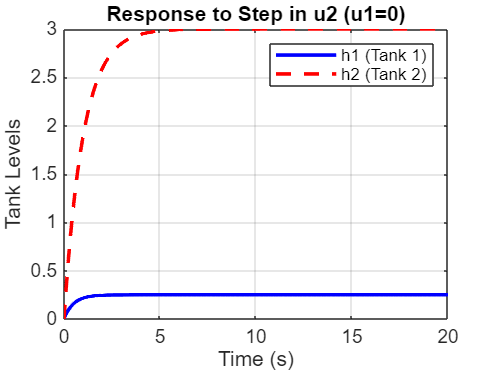

u1 = zeros(size(t));
u2 = ones(size(t));
u = [u1; u2]';

[y2,~] = lsim(G,u,t);

figure;
plot(t,y2(:,1),'b','LineWidth',1.8); hold on;
plot(t,y2(:,2),'r--','LineWidth',1.8);
grid on;
legend('h1 (Tank 1)','h2 (Tank 2)');
title('Response to Step in u2 (u1=0)');
xlabel('Time (s)');
ylabel('Tank Levels');

TASK-B

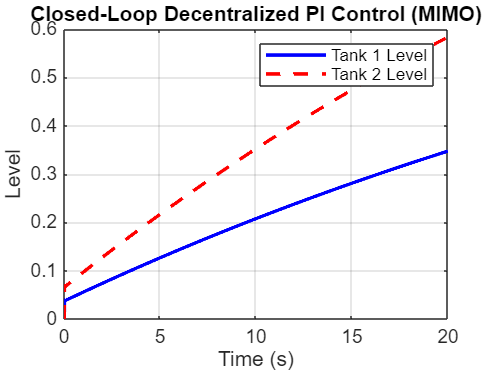


r1 = ones(size(t));      
r2 = 1.5*ones(size(t));  

Kp1 = 1.5;  Ki1 = 0.8;
Kp2 = 1.2;  Ki2 = 0.6;

h1 = zeros(size(t));
h2 = zeros(size(t));

u1 = zeros(size(t));
u2 = zeros(size(t));

e1_int = 0;
e2_int = 0;

dt = t(2) - t(1);


for i = 2:length(t)

    e1 = r1(i) - h1(i-1);
    e2 = r2(i) - h2(i-1);

    u1(i) = Kp1*e1 + Ki1*e1_int;
    u2(i) = Kp2*e2 + Ki2*e2_int;

    e1_int = e1_int + e1*dt;
    e2_int = e2_int + e2*dt;

    u_vec = [u1(i-1)  u2(i-1);
             u1(i)    u2(i)];

    t_step = [0 dt];
    x_prev = [h1(i-1) h2(i-1)];

    y_step = lsim(G, u_vec, t_step, x_prev);

    
    h1(i) = y_step(end,1);
    h2(i) = y_step(end,2);

end

figure;
plot(t,h1,'b','LineWidth',1.8); hold on;
plot(t,h2,'r--','LineWidth',1.8);
grid on;
legend('Tank 1 Level','Tank 2 Level');
title('Closed-Loop Decentralized PI Control (MIMO)');
xlabel('Time (s)');
ylabel('Level');

TASK-C

% Final reference values
r1_final = r1(end);
r2_final = r2(end);

% Step response metrics
info_h1 = stepinfo(h1, t, r1_final);
info_h2 = stepinfo(h2, t, r2_final);

% Final values from simulation
h1_final = h1(end);
h2_final = h2(end);

% Interaction analysis table
InteractionTable = table( ...
    h1_final, info_h1.SettlingTime, ...
    h2_final, info_h2.SettlingTime, ...
    'VariableNames', ...
    {'Final_h1','Ts_h1','Final_h2','Ts_h2'} ...
)

InteractionTable = 1×4 table
    Final_h1    Ts_h1    Final_h2    Ts_h2
    ________    _____    ________    _____

    0.34738      NaN     0.58334      NaN 


From the closed-loop response, we observe that changes in u1�, made to regulate h1�, also cause a change in h2. This is due to the cross-coupling transfer path G21(s). Similarly, changes in u2affect h1� through G12�(s).

As a result, each PI controller treats the other tank as a disturbance, leading to small overshoots and increased settling times. The outputs do not behave independently, which confirms that MIMO systems exhibit interaction and cannot be treated as two isolated SISO loops.

TASK-D

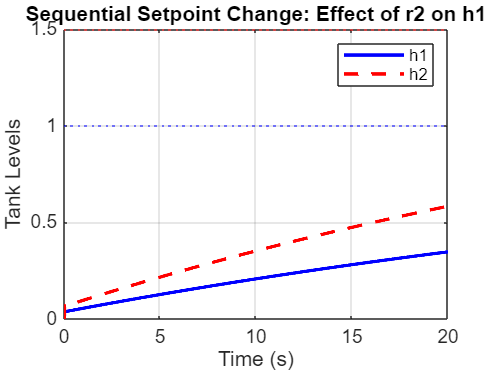

r1 = ones(size(t));          
r2 = ones(size(t));          
r2(t >= 10) = 1.5;           

figure;
plot(t,h1,'b','LineWidth',1.8); hold on;
plot(t,h2,'r--','LineWidth',1.8);
yline(1,'b:');
yline(1.5,'r:');
grid on;
legend('h1','h2');
title('Sequential Setpoint Change: Effect of r2 on h1');
xlabel('Time (s)');
ylabel('Tank Levels');

The control loops cannot be tuned independently because changing one reference or input affects multiple outputs. More advanced methods such as decouplers or multivariable control strategies would be required to improve performance.